# **Example of figures for chemostat/retentostat fits with model variant complex**

This model variant was not part of the main manuscript, but it was presented in the supplementary section 10 as an attempt to fit both systems (chemostat/retentostat) with a complex model.

## Calling Parameters

load('C:\Doctorado\Programa\Nuevo_PECCAD\NEW ATRAZINE\GENE BASED MODELS\AT_engi_soil\example_parameter_fits\variant_complex_best.mat')
p1 = p; 

## Calling fixed parameters

delta13_I = (-29/1000);
AT_tot    = 30000*(8*12/216);                  % Input of AT, including light and heavy isotopologues [microg C/L]
frac_coef = -0.0054;   %-0.0054                % Initial fraction Coefficient for the AT applied in the experiment "epsilon" initial *** parameter *** [-5 -6]
SN        = (delta13_I+1)*0.011180;            % Initial C13/C12. -29 is taken from Beno´s paper (-29 per mil)

q(2) = AT_tot;                                  % Concentration of light AT in the inlet [microg C/L]
q(3) = AT_tot*SN;                               % Concentration of heavier AT in the inlet [microg C/L]
q(4) = 1;                                       % Factor for chemostat (1) and retentostat (0).
q(5) = 8*12/216;                                % mg C/mg AT
q(6) = 8*12/197;                                % mg C/mg HY
q(7) = 1e-15;                                   % Volume of a single bacterium [L]
q(8) = 1+frac_coef;                             % Isotopic fractionation factor "alpha" that comes from the enzymatic activity [-]
q(9) = 0.011180;                                % reference isotope ratio of VPDB (Vienna Pee Dee Belemnite) [-]
q(10)= 0.1;                                     % Switch parameter

## Running ODE

% ODE options %
abstol = 1e-9;
reltol = 1e-7;
o_opts = odeset('AbsTol',abstol,'RelTol',reltol,'Events',@stopevent,'NonNegative',1:11);

% Extra Parameters %
T_bioC   = 3.66e11;  % Initial Biomass [cells/L]
fcell    = 10^p1(7);
C_AT     = q(5);     % µg C/µg AT
C_HY     = q(6);     % µg C/µg HY
ATinitC  = 87*C_AT;  % µg C/ L OUTSIDE
HYinitC  = 18*C_HY;  % µg C/ L OUTSIDE
isf      = q(8);     % Isotopic fractionation factor (?)
Ref      = q(9);     % reference isotope ratio of VPDB
T_bioR   = 5.4e10;   % Initial Biomass [cells/L]
ATinitR  = 100*C_AT; % microgr/ L OUTSIDE
HYinitR  = 250*C_HY; % microgr/ L OUTSIDE 
V_u      = q(7);     % Volume of a single bacterium [L]

% Initial Conditions %
        c(1)    = T_bioC*fcell/2;                % Active growing bacteria A biomass [µg C/L]
        c(2)    = T_bioC*fcell/2;                % Active non-growing bacteria A biomass [µg C/L]
        c(3)    = ATinitC/2;                     % Lighter AT inside the growing cell in the system in solution [µg C/L]
        c(4)    = ATinitC*SN/2;                  % Heavier AT inside the growing cell in the system in solution [µg C/L]
        c(5)    = ATinitC/2;                     % Lighter AT inside the non-growing cell in the system in solution [µg C/L]
        c(6)    = ATinitC*SN/2;                  % Heavier AT inside the non-growing cell in the system in solution [µg C/L]
        c(7)    = ATinitC;                       % Lighter AT outside the cell in the system in solution [µg C/L]
        c(8)    = ATinitC*SN;                    % Heavier AT outside the cell in the system in solution [µg C/L]        
        c(9)    = HYinitC/2;                     % Hydroxyatrazine INSIDE growing cell [µg C/L]
        c(10)   = HYinitC/2;                     % Hydroxyatrazine INSIDE non-growing cell [µg C/L]
        c(11)   = HYinitC;                       % Hydroxyatrazine outisde the cell [µg C/L]

% First Dilution rate chemostat %
q(1) = 0.023*24;    % Dilution rate coeficient (1/d)
t    = [0 20];
tic
[ty,cu] = ode15s(@variant_complex,t,c,o_opts,p1',q);

% Second Dilution rate chemostat %
q(1) = 0.032*24;       % Dilution rate coeficient (1/d)        
t1   = [20 31];

        c(1)    = cu(end,1);                % Active growing bacteria A biomass [µg C/L]
        c(2)    = cu(end,2);                % Active non-growing bacteria A biomass [µg C/L]
        c(3)    = cu(end,3);                % Lighter AT inside the growing cell in the system in solution [µg C/L]
        c(4)    = cu(end,4);                % Heavier AT inside the growing cell in the system in solution [µg C/L]
        c(5)    = cu(end,5);                % Lighter AT inside the non-growing cell in the system in solution [µg C/L]
        c(6)    = cu(end,6);                % Heavier AT inside the non-growing cell in the system in solution [µg C/L]
        c(7)    = cu(end,7);                % Lighter AT outside the cell in the system in solution [µg C/L]
        c(8)    = cu(end,8);                % Heavier AT outside the cell in the system in solution [µg C/L]        
        c(9)    = cu(end,9);                % Hydroxyatrazine INSIDE growing cell [µg C/L]
        c(10)   = cu(end,10);               % Hydroxyatrazine INSIDE non-growing cell [µg C/L]
        c(11)   = cu(end,11);               % Hydroxyatrazine outisde the cell [µg C/L]

tic
[ty1,cu1] = ode15s(@variant_complex,t1,c,o_opts,p1',q);

% Third Dilution rate chemostat %
q(1) = 0.048*24;       % Dilution rate coeficient (1/d)        
t2   = [31 37];

        c(1)    = cu1(end,1);                % Active growing bacteria A biomass [µg C/L]
        c(2)    = cu1(end,2);                % Active non-growing bacteria A biomass [µg C/L]
        c(3)    = cu1(end,3);                % Lighter AT inside the growing cell in the system in solution [µg C/L]
        c(4)    = cu1(end,4);                % Heavier AT inside the growing cell in the system in solution [µg C/L]
        c(5)    = cu1(end,5);                % Lighter AT inside the non-growing cell in the system in solution [µg C/L]
        c(6)    = cu1(end,6);                % Heavier AT inside the non-growing cell in the system in solution [µg C/L]
        c(7)    = cu1(end,7);                % Lighter AT outside the cell in the system in solution [µg C/L]
        c(8)    = cu1(end,8);                % Heavier AT outside the cell in the system in solution [µg C/L]        
        c(9)    = cu1(end,9);                % Hydroxyatrazine INSIDE growing cell [µg C/L]
        c(10)   = cu1(end,10);               % Hydroxyatrazine INSIDE non-growing cell [µg C/L]
        c(11)   = cu1(end,11);               % Hydroxyatrazine outisde the cell [µg C/L]

tic
[ty2,cu2] = ode15s(@variant_complex,t2,c,o_opts,p1',q);

% Fourth Dilution rate chemostat %
q(1) = 0.056*24;       % Dilution rate coeficient (1/d)        
t3   = [37 42];

        c(1)    = cu2(end,1);                % Active growing bacteria A biomass [µg C/L]
        c(2)    = cu2(end,2);                % Active non-growing bacteria A biomass [µg C/L]
        c(3)    = cu2(end,3);                % Lighter AT inside the growing cell in the system in solution [µg C/L]
        c(4)    = cu2(end,4);                % Heavier AT inside the growing cell in the system in solution [µg C/L]
        c(5)    = cu2(end,5);                % Lighter AT inside the non-growing cell in the system in solution [µg C/L]
        c(6)    = cu2(end,6);                % Heavier AT inside the non-growing cell in the system in solution [µg C/L]
        c(7)    = cu2(end,7);                % Lighter AT outside the cell in the system in solution [µg C/L]
        c(8)    = cu2(end,8);                % Heavier AT outside the cell in the system in solution [µg C/L]        
        c(9)    = cu2(end,9);                % Hydroxyatrazine INSIDE growing cell [µg C/L]
        c(10)   = cu2(end,10);               % Hydroxyatrazine INSIDE non-growing cell [µg C/L]
        c(11)   = cu2(end,11);               % Hydroxyatrazine outisde the cell [µg C/L]
            
tic
[ty3,cu3] = ode15s(@variant_complex,t3,c,o_opts,p1',q);  

% Fifth Dilution rate chemostat %
q(1) = 0.068*24;       % Dilution rate coeficient (1/d)        
t4   = [42 45];

        c(1)    = cu3(end,1);                % Active growing bacteria A biomass [µg C/L]
        c(2)    = cu3(end,2);                % Active non-growing bacteria A biomass [µg C/L]
        c(3)    = cu3(end,3);                % Lighter AT inside the growing cell in the system in solution [µg C/L]
        c(4)    = cu3(end,4);                % Heavier AT inside the growing cell in the system in solution [µg C/L]
        c(5)    = cu3(end,5);                % Lighter AT inside the non-growing cell in the system in solution [µg C/L]
        c(6)    = cu3(end,6);                % Heavier AT inside the non-growing cell in the system in solution [µg C/L]
        c(7)    = cu3(end,7);                % Lighter AT outside the cell in the system in solution [µg C/L]
        c(8)    = cu3(end,8);                % Heavier AT outside the cell in the system in solution [µg C/L]        
        c(9)    = cu3(end,9);                % Hydroxyatrazine INSIDE growing cell [µg C/L]
        c(10)   = cu3(end,10);               % Hydroxyatrazine INSIDE non-growing cell [µg C/L]
        c(11)   = cu3(end,11);               % Hydroxyatrazine outisde the cell [µg C/L]   

tic
[ty4,cu4] = ode15s(@variant_complex,t4,c,o_opts,p1',q);

% First Dilution rate retentostat %

q(1)  = 0.02*24;       % Dilution rate coeficient (1/d)        
t5    = [0 40];
q(4)  = 0;                                       % Factor for chemostat (1) and retentostat (0).

        c(1)    = T_bioR*fcell/2;         % Active growing bacteria A biomass [µg C/L]
        c(2)    = T_bioR*fcell/2;         % Active non-growing bacteria A biomass [µg C/L]
        c(3)    = ATinitR/2;              % Lighter AT inside the growing cell in the system in solution [µg C/L]
        c(4)    = ATinitR*SN/2;           % Heavier AT inside the growing cell in the system in solution [µg C/L]
        c(5)    = ATinitR/2;              % Lighter AT inside the non-growing cell in the system in solution [µg C/L]
        c(6)    = ATinitR*SN/2;           % Heavier AT inside the non-growing cell in the system in solution [µg C/L]
        c(7)    = ATinitR;                % Lighter AT outside the cell in the system in solution [µg C/L]
        c(8)    = ATinitR*SN;             % Heavier AT outside the cell in the system in solution [µg C/L]        
        c(9)    = HYinitR/2;              % Hydroxyatrazine INSIDE growing cell [µg C/L]
        c(10)   = HYinitR/2;              % Hydroxyatrazine INSIDE non-growing cell [µg C/L]
        c(11)   = HYinitR;                % Hydroxyatrazine outisde the cell [µg C/L]

tic
[ty5,cu5] = ode15s(@variant_complex,t5,c,o_opts,p1',q);

## Pros-Processing of the outputs

% Chemostat %
        Lcellc       = vertcat(cu(:,1),cu1(:,1),cu2(:,1),cu3(:,1),cu4(:,1))/fcell;      % Biomass 
        Lcellc2      = vertcat(cu(:,2),cu1(:,2),cu2(:,2),cu3(:,2),cu4(:,2))/fcell;      % Biomass 
        TotalC       = Lcellc + Lcellc2;                                                % Total AT

        AT_outlc     = vertcat(cu(:,7),cu1(:,7),cu2(:,7),cu3(:,7),cu4(:,7))/C_AT;       % AT lighter
        AT_outhc     = vertcat(cu(:,8),cu1(:,8),cu2(:,8),cu3(:,8),cu4(:,8))/C_AT;       % AT heavier 
        AT_outTc     = AT_outlc + AT_outhc;                                             % Total AT

        HY_outc      = vertcat(cu(:,11),cu1(:,11),cu2(:,11),cu3(:,11),cu4(:,11))/C_HY;  % HY
        
        Timeoc       = vertcat(ty,ty1,ty2,ty3,ty4);                                     % Time
% Retentostat %
        Lcellr       = (cu5(:,1))/fcell;    % Biomass 
        Lcellr2      = (cu5(:,2))/fcell;    % Biomass 
        TotalC2      = Lcellr + Lcellr2;    % Total AT

        AT_outlr     = (cu5(:,7))/C_AT;     % AT lighter
        AT_outhr     = (cu5(:,8))/C_AT;     % AT heavier 
        AT_outTr     = AT_outlr + AT_outhr; % Total AT

        HY_outr      = (cu5(:,11))/C_HY;    % HY
        
        Timeor       = (ty5);               % Time 
% Enrichment Factor Chemostat %
d_not_i = -29/1000;  % epsilon-notation for the inlet.
d_not_o = (vertcat(cu(:,8),cu1(:,8),cu2(:,8),cu3(:,8),cu4(:,8))./...
          vertcat(cu(:,7),cu1(:,7),cu2(:,7),cu3(:,7),cu4(:,7))/Ref)-1;  % ?-notation for the outlet in the chemostat.
EF_Ch   = (d_not_i - d_not_o);
% Enrichment Factor Retentostat %
d_not_oR = (cu5(:,8)./cu5(:,7)/Ref)-1;  % epsilon-notation for the outlet in the chemostat.
EF_Rt    = (d_not_i - d_not_oR);

## Plotting

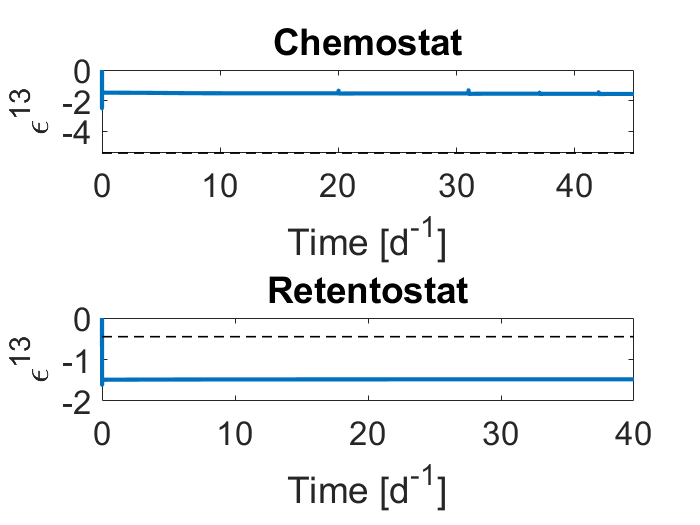

% Enrichment Factor %
figure ('Name','Enrichment Factor Chemostat')
subplot (2,1,1);
plot(Timeoc,EF_Ch*1e3,'LineWidth',2.5)
hold on
plot([0 45],[-5.4 -5.4],'--','Color','black','LineWidth',1)
title('Chemostat')
ylabel('\epsilon^{13}')
xlabel('Time [d^{-1}]')
box on
ax = gca;
ax.FontSize = 20;
xlim([0 45])
hold off

subplot (2,1,2);
plot(ty5,EF_Rt*1e3,'LineWidth',2.5)
hold on
plot([0 40],[-0.45 -0.45],'--','Color','black','LineWidth',1)
xlabel('Time [d^{-1}]')
title('Retentostat')
box on
ylabel('\epsilon^{13}')
ax = gca;
ax.FontSize = 20;
hold off


% Calling Data %

load('chemostat_data_plot_test.txt')
Time1 = chemostat_data_plot_test(:,1);
Data1 = chemostat_data_plot_test(:,3);

load('retentostat_data_plot_test.txt')
Time = retentostat_data_plot_test(:,1);
Data = retentostat_data_plot_test(:,2);


## Chemostat Plotting

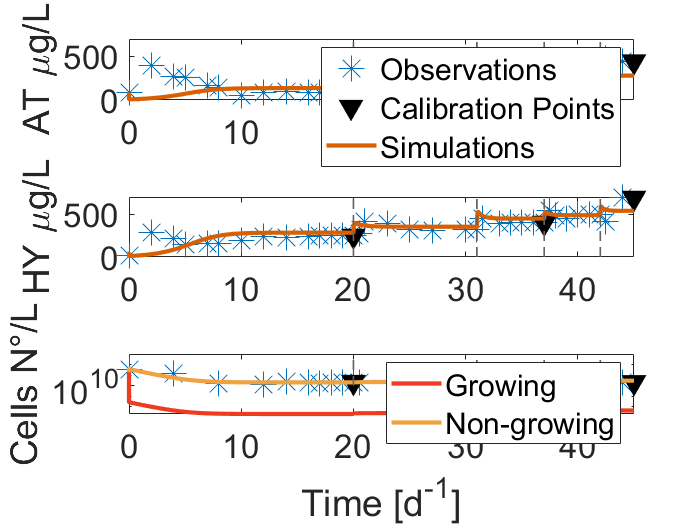

% Atrazine %

figure ('Name','AT-Chemostat')
subplot (3,1,1);
A=plot(Time1(1:36),Data1(1:36),'*','MarkerSize',15);
hold on
B=plot(Time1(14),Data1(14),'v', 'MarkerSize',12,'MarkerEdgeColor','k','MarkerFaceColor','k');
plot(Time1(27),Data1(27),'v', 'MarkerSize',12,'MarkerEdgeColor','k','MarkerFaceColor','k')
plot(Time1(37),Data1(37),'v', 'MarkerSize',12,'MarkerEdgeColor','k','MarkerFaceColor','k')
C=plot(Timeoc,AT_outTc,'LineWidth',2.5,'color',[217/256,95/256,2/256]);
plot([20 20],[0 700],'--','Color',[99/256 99/256 99/256],'LineWidth',1)
plot([31 31],[0 700],'--','Color',[99/256 99/256 99/256],'LineWidth',1)
plot([37 37],[0 700],'--','Color',[99/256 99/256 99/256],'LineWidth',1)
plot([42 42],[0 700],'--','Color',[99/256 99/256 99/256],'LineWidth',1)
ylabel('AT \mug/L')
ax = gca;
ax.FontSize = 20;
legend([A B C],'Observations','Calibration Points','Simulations')
hold off

% Hydroxyatrazine %

subplot (3,1,2);
plot(Time1(49:83),Data1(49:83),'*', 'MarkerSize',15)
hold on
plot(Time1(62),Data1(62),'v', 'MarkerSize',12,'MarkerEdgeColor','k','MarkerFaceColor','k')
plot(Time1(75),Data1(75),'v', 'MarkerSize',12,'MarkerEdgeColor','k','MarkerFaceColor','k')
plot(Time1(84),Data1(84),'v', 'MarkerSize',12,'MarkerEdgeColor','k','MarkerFaceColor','k')
plot(Timeoc,HY_outc,'LineWidth',2.5,'color',[217/256,95/256,2/256])
plot([20 20],[0 700],'--','Color',[99/256 99/256 99/256],'LineWidth',1)
plot([31 31],[0 700],'--','Color',[99/256 99/256 99/256],'LineWidth',1)
plot([37 37],[0 700],'--','Color',[99/256 99/256 99/256],'LineWidth',1)
plot([42 42],[0 700],'--','Color',[99/256 99/256 99/256],'LineWidth',1)
ylabel('HY \mug/L')
ax = gca;
ax.FontSize = 20;
hold off

% Biomass %

subplot (3,1,3);
semilogy(Time1(96:121),Data1(96:121),'*', 'MarkerSize',15)
hold on
semilogy(Time1(105),Data1(105),'v', 'MarkerSize',12,'MarkerEdgeColor','k','MarkerFaceColor','k')
semilogy(Time1(115),Data1(115),'v', 'MarkerSize',12,'MarkerEdgeColor','k','MarkerFaceColor','k')
semilogy(Time1(122),Data1(122),'v', 'MarkerSize',12,'MarkerEdgeColor','k','MarkerFaceColor','k')
semilogy(Timeoc,TotalC,'LineWidth',2.5,'color',[217/256,95/256,2/256])
A1=semilogy(Timeoc,Lcellc,'LineWidth',2.5,'color',[240/256,59/256,32/256]);
B1=semilogy(Timeoc,Lcellc2,'LineWidth',2.5,'color',[241/256,163/256,64/256]);
semilogy([20 20],[1e10 1e13],'--','Color',[99/256 99/256 99/256],'LineWidth',1)
semilogy([31 31],[1e10 1e13],'--','Color',[99/256 99/256 99/256],'LineWidth',1)
semilogy([37 37],[1e10 1e13],'--','Color',[99/256 99/256 99/256],'LineWidth',1)
semilogy([42 42],[1e10 1e13],'--','Color',[99/256 99/256 99/256],'LineWidth',1)
xlabel('Time [d^{-1}]')
ylabel('Cells N°/L')
ax = gca;
ax.FontSize = 20;
legend([A1 B1],'Growing','Non-growing')
hold off  

## Retentostat Plotting

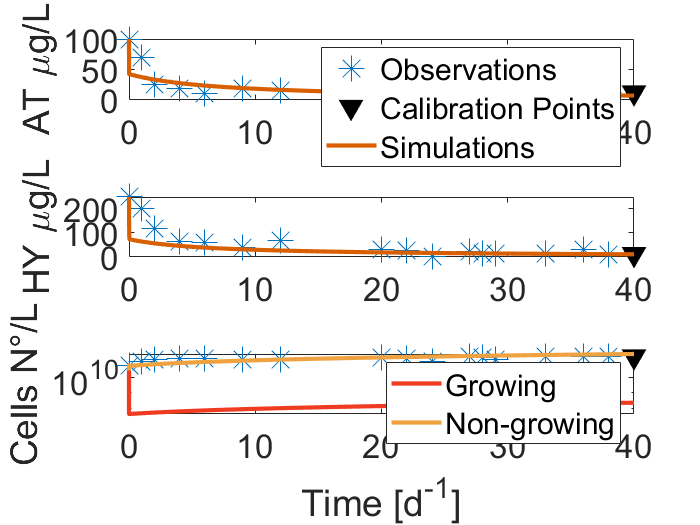

figure ('Name','AT-Retentostat')
subplot (3,1,1);
A=plot(Time(1:16),Data(1:16),'*', 'MarkerSize',15);
hold on
B=plot(Time(17),Data(17),'v', 'MarkerSize',12,'MarkerEdgeColor','k','MarkerFaceColor','k');
C=plot(Timeor,AT_outTr,'LineWidth',2.5,'color',[217/256,95/256,2/256]);
ylabel('AT \mug/L')
ax = gca;
ax.FontSize = 20;
legend([A B C],'Observations','Calibration Points','Simulations')
hold off

subplot (3,1,2);
A=plot(Time(18:33),Data(18:33),'*','MarkerSize',15);
hold on
B=plot(Time(34),Data(34),'v', 'MarkerSize',12,'MarkerEdgeColor','k','MarkerFaceColor','k');
C=plot(Timeor,HY_outr,'LineWidth',2.5,'color',[217/256,95/256,2/256]);
ylabel('HY \mug/L')
ax = gca;
ax.FontSize = 20;
hold off

subplot (3,1,3);
A=semilogy(Time(35:end-1),Data(35:end-1),'*', 'MarkerSize',15);
hold on
B=plot(Time(end),Data(end),'v', 'MarkerSize',12,'MarkerEdgeColor','k','MarkerFaceColor','k');
C=semilogy(Timeor,TotalC2,'LineWidth',2.5,'color',[217/256,95/256,2/256]);
A1=semilogy(Timeor,Lcellr,'LineWidth',2.5,'color',[240/256,59/256,32/256]);
B1=semilogy(Timeor,Lcellr2,'LineWidth',2.5,'color',[241/256,163/256,64/256]);
legend([A1 B1],'Growing','Non-growing')
xlabel('Time [d^{-1}]')
ylabel('Cells N°/L')
ax = gca;
ax.FontSize = 20;
hold off